Analysis and Comparison 

%% Flow Field Analysis, Quantitative Error Metrics, and CFD Benchmark
clear; clc; close all;

% --- 1. Load Data and Trained Geometry-Conditioned Model ---
dataFilePath  = fullfile(pwd, 'DeepCFD_preprocessed.mat');
modelFilePath = fullfile(pwd, 'PINN_Trained_Model.mat');

if ~exist(dataFilePath, 'file') || ~exist(modelFilePath, 'file')
    error('Ensure both DeepCFD_preprocessed.mat and PINN_Trained_Model.mat exist in the current folder.');
end

load(dataFilePath, 'X_val', 'Y_val', 'normStats');
load(modelFilePath, 'net', 'valHistory');

% --- 2. Grid and Physical Dimension Setup ---
[Ny, Nx, ~, ~] = size(Y_val);
x_vec = linspace(0.0, 2.0, Nx);
y_vec = linspace(-0.5, 0.5, Ny);
[X_grid, Y_grid] = meshgrid(x_vec, y_vec);

% Physical un-normalization limits
u_min = normStats.Y_min(1, 1, 1); u_max = normStats.Y_max(1, 1, 1);
v_min = normStats.Y_min(1, 1, 2); v_max = normStats.Y_max(1, 1, 2);
p_min = normStats.Y_min(1, 1, 3); p_max = normStats.Y_max(1, 1, 3);

% Extract Ground-Truth OpenFOAM fields (Physical units)
Ux_cfd = 0.5 * (squeeze(Y_val(:, :, 1, 1)) + 1) * (u_max - u_min) + u_min;
Uy_cfd = 0.5 * (squeeze(Y_val(:, :, 2, 1)) + 1) * (v_max - v_min) + v_min;
P_cfd  = 0.5 * (squeeze(Y_val(:, :, 3, 1)) + 1) * (p_max - p_min) + p_min;

% --- 3. Construct 3-Channel Evaluation Tensor: [x; y; SDF] ---
SDF_val = squeeze(X_val(:, :, 1, 1)); % Normalized obstacle SDF
eval_pts = dlarray([single(X_grid(:))'; single(Y_grid(:))'; single(SDF_val(:))'], 'CB');

% Benchmark inference latency (100 passes)
numRuns = 100;
tic;
for i = 1:numRuns
    pred_dl = forward(net, eval_pts);
end
t_infer_avg = (toc / numRuns) * 1000; % ms

% Convert predictions back to physical units
Ux_pinn = 0.5 * (reshape(extractdata(pred_dl(1, :)), [Ny, Nx]) + 1) * (u_max - u_min) + u_min;
Uy_pinn = 0.5 * (reshape(extractdata(pred_dl(2, :)), [Ny, Nx]) + 1) * (v_max - v_min) + v_min;
P_pinn  = 0.5 * (reshape(extractdata(pred_dl(3, :)), [Ny, Nx]) + 1) * (p_max - p_min) + p_min;

% Compute spatial absolute error fields
err_Ux = abs(Ux_pinn - Ux_cfd);
err_Uy = abs(Uy_pinn - Uy_cfd);
err_P  = abs(P_pinn - P_cfd);

% --- 4. Quantitative Validation Metrics ---
rel_L2 = @(pred, true) norm(pred(:) - true(:)) / norm(true(:));
mae    = @(pred, true) mean(abs(pred(:) - true(:)));

metricsTable = table(...
    {'Horizontal Velocity (Ux)'; 'Vertical Velocity (Uy)'; 'Kinematic Pressure (p)'}, ...
    [rel_L2(Ux_pinn, Ux_cfd); rel_L2(Uy_pinn, Uy_cfd); rel_L2(P_pinn, P_cfd)], ...
    [mae(Ux_pinn, Ux_cfd); mae(Uy_pinn, Uy_cfd); mae(P_pinn, P_cfd)], ...
    'VariableNames', {'Variable', 'Relative_L2_Error', 'MAE'});

fprintf('\n================ QUANTITATIVE VALIDATION METRICS ================\n');


================ QUANTITATIVE VALIDATION METRICS ================


disp(metricsTable);

              Variable              Relative_L2_Error       MAE   
    ____________________________    _________________    _________

    {'Horizontal Velocity (Ux)'}         0.29193          0.025469
    {'Vertical Velocity (Uy)'  }         0.80297         0.0098697
    {'Kinematic Pressure (p)'  }          1.5602           0.01262



fprintf('Average PINN Forward Pass Time: %.3f ms (Grid: %d x %d)\n', t_infer_avg, Ny, Nx);

Average PINN Forward Pass Time: 13.199 ms (Grid: 172 x 79)


fprintf('Typical simpleFoam Iteration Time: ~1.2 - 3.5 s per case\n');

Typical simpleFoam Iteration Time: ~1.2 - 3.5 s per case


fprintf('=================================================================\n');

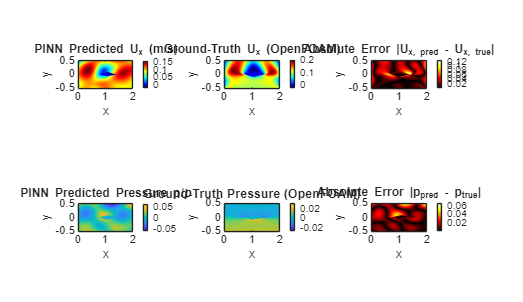


% --- 5. Flow Field Visualizations (Predicted vs Ground Truth vs Error) ---
fig_fields = figure('Position', [50, 50, 1300, 750], 'Color', 'w');

% Horizontal Velocity (Ux)
subplot(2, 3, 1);
contourf(X_grid, Y_grid, Ux_pinn, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'jet'); title('PINN Predicted U_x (m/s)'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 2);
contourf(X_grid, Y_grid, Ux_cfd, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'jet'); title('Ground-Truth U_x (OpenFOAM)'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 3);
contourf(X_grid, Y_grid, err_Ux, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'hot'); title('Absolute Error |U_{x, pred} - U_{x, true}|'); xlabel('x'); ylabel('y'); axis equal tight;

% Kinematic Pressure (p/rho)
subplot(2, 3, 4);
contourf(X_grid, Y_grid, P_pinn, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'parula'); title('PINN Predicted Pressure p/\rho'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 5);
contourf(X_grid, Y_grid, P_cfd, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'parula'); title('Ground-Truth Pressure (OpenFOAM)'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 6);
contourf(X_grid, Y_grid, err_P, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'hot'); title('Absolute Error |p_{pred} - p_{true}|'); xlabel('x'); ylabel('y'); axis equal tight;

% --- 6. Centerline and Wake Profile Slices ---
mid_y_idx  = round(Ny / 2);      % Channel centerline (y = 0)
wake_x_idx = round(Nx * 0.70);   % Wake region (x ~ 1.4 m)

fig_profiles = figure('Position', [100, 100, 1100, 450], 'Color', 'w');

subplot(1, 2, 1);
plot(x_vec, Ux_cfd(mid_y_idx, :), 'k-', 'LineWidth', 2, 'DisplayName', 'Ground Truth (OpenFOAM)');
hold on;
plot(x_vec, Ux_pinn(mid_y_idx, :), 'r--', 'LineWidth', 2, 'DisplayName', 'PINN Prediction');
grid on; xlabel('x [m]'); ylabel('U_x [m/s]');
title('Centerline Velocity Profile (y = 0)');
legend('Location', 'best');

subplot(1, 2, 2);
plot(y_vec, Ux_cfd(:, wake_x_idx), 'k-', 'LineWidth', 2, 'DisplayName', 'Ground Truth (OpenFOAM)');
hold on;
plot(y_vec, Ux_pinn(:, wake_x_idx), 'r--', 'LineWidth', 2, 'DisplayName', 'PINN Prediction');
grid on; xlabel('y [m]'); ylabel('U_x [m/s]');
title(sprintf('Wake Velocity Profile (x = %.2f m)', x_vec(wake_x_idx)));
legend('Location', 'best');

% Export high-resolution plots
exportgraphics(fig_fields, 'Geometry_Conditioned_Fields.png', 'Resolution', 300);

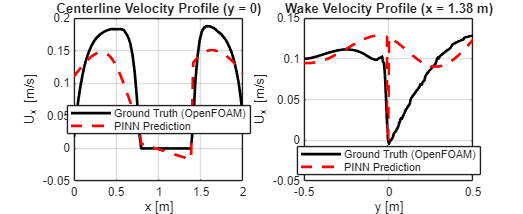

exportgraphics(fig_profiles, 'Geometry_Conditioned_Profiles.png', 'Resolution', 300);


save('Final_Analysis_Results.mat', 'metricsTable', 't_infer_avg', 'err_Ux', 'err_Uy', 'err_P');
fprintf('Analysis executed successfully. Plots saved to your folder.\n');

Analysis executed successfully. Plots saved to your folder.
